# Tune Control for Electric VTOL Drone Propeller Motor

This example shows how to design a control system for a VTOL aircraft.  

Copyright 2025 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('EVTOLDesignOverview.html')).

## Control Architecture

The outer-loop control system is for navigation and guidance: 

- Responsible for the overall position control and navigation of the aircraft.

- Utilizes a PID cascaded system for position control, where a proportional controller determines the reference velocity, and a PID controller manages velocity control.

- Includes yaw angle control through autopilot guidance loops.

The inner-loop control system controls the altitude:

- Manages the roll, pitch, and yaw of the aircraft.

- Uses a PID cascaded system for attitude control, where a proportional controller provides the reference turn rate, and a PID controller manages turn-rate control.

- Uses motor mixing and tilt mixing to adjust motor speeds for control in the z-axis, roll axis, and pitch axis.

- Adjusts the tilt angles of the front motors for yaw and x-axis control.

- Involves adjusting all motor speeds to control altitude, with a linear response that is decoupled from other axes.

This control architecture maintains stability and responsiveness of the VTOL aircraft during different phases of flight by effectively separating high-level navigation tasks from low-level attitude and motor control tasks.

## Control Tuning

In this example, you tune the motor loop and check the stability of the plant and controllers with the powertrain added to the model.

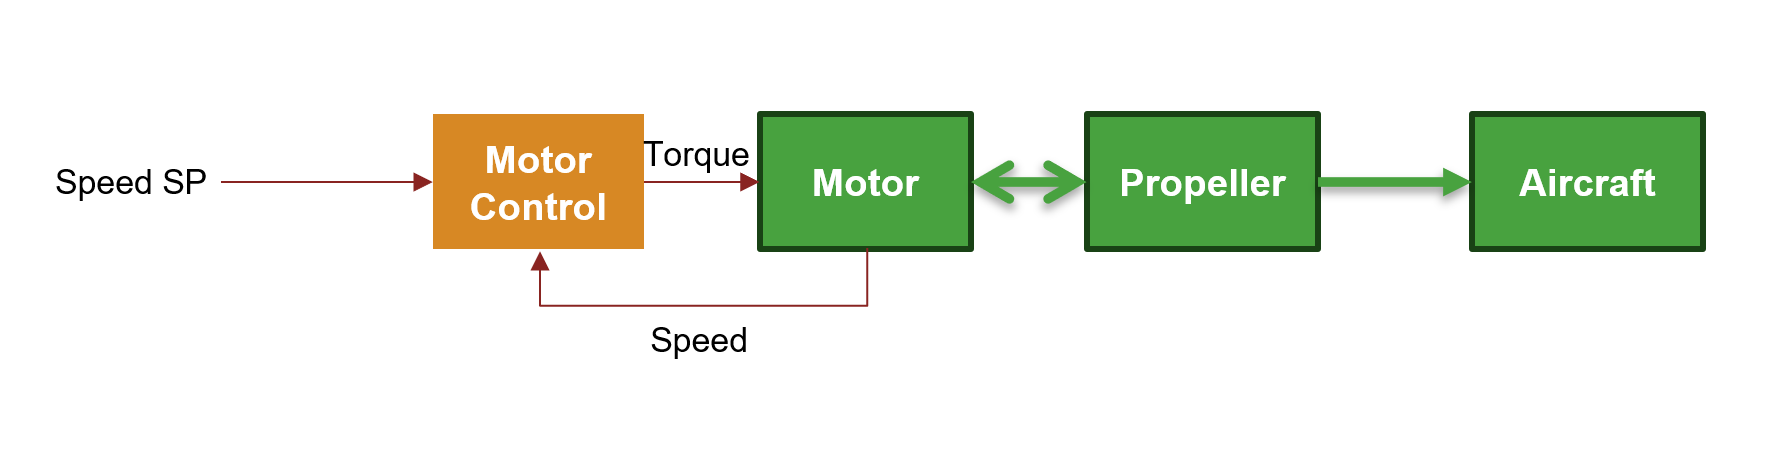

Inspect the simulation output before tuning the controllers.

SetupPlant;

Initialized VTOL model.


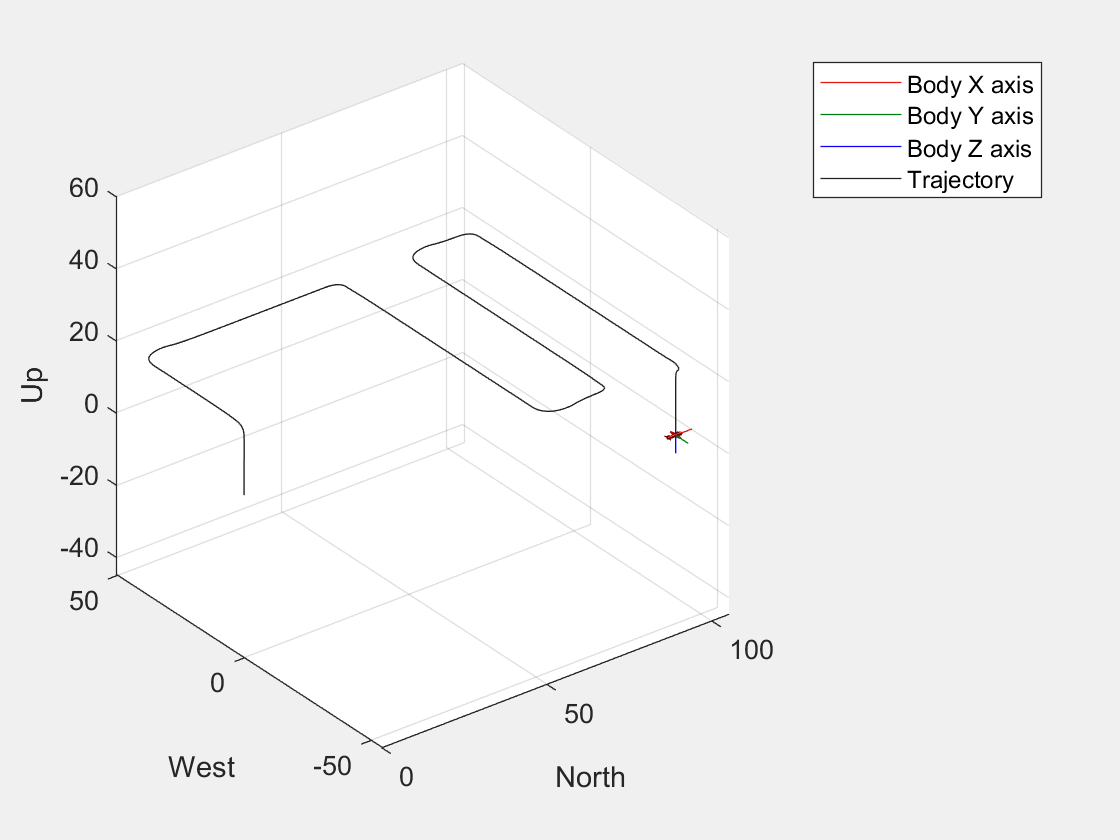

SetupCityMission;
SetupHoverConfiguration;
SetupHoverGuidanceMission;
Visualization = 1;
load('MotorPID');
BatteryParameter;
simDataUntuned = sim(mdl);

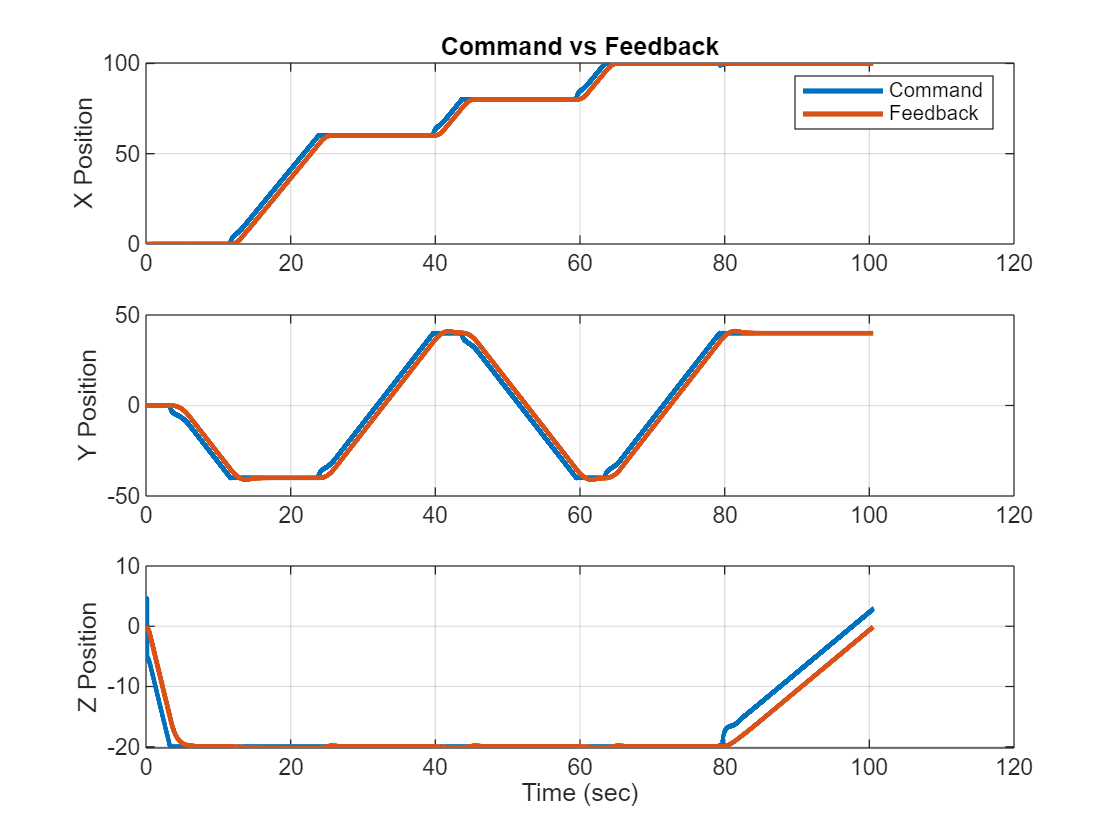

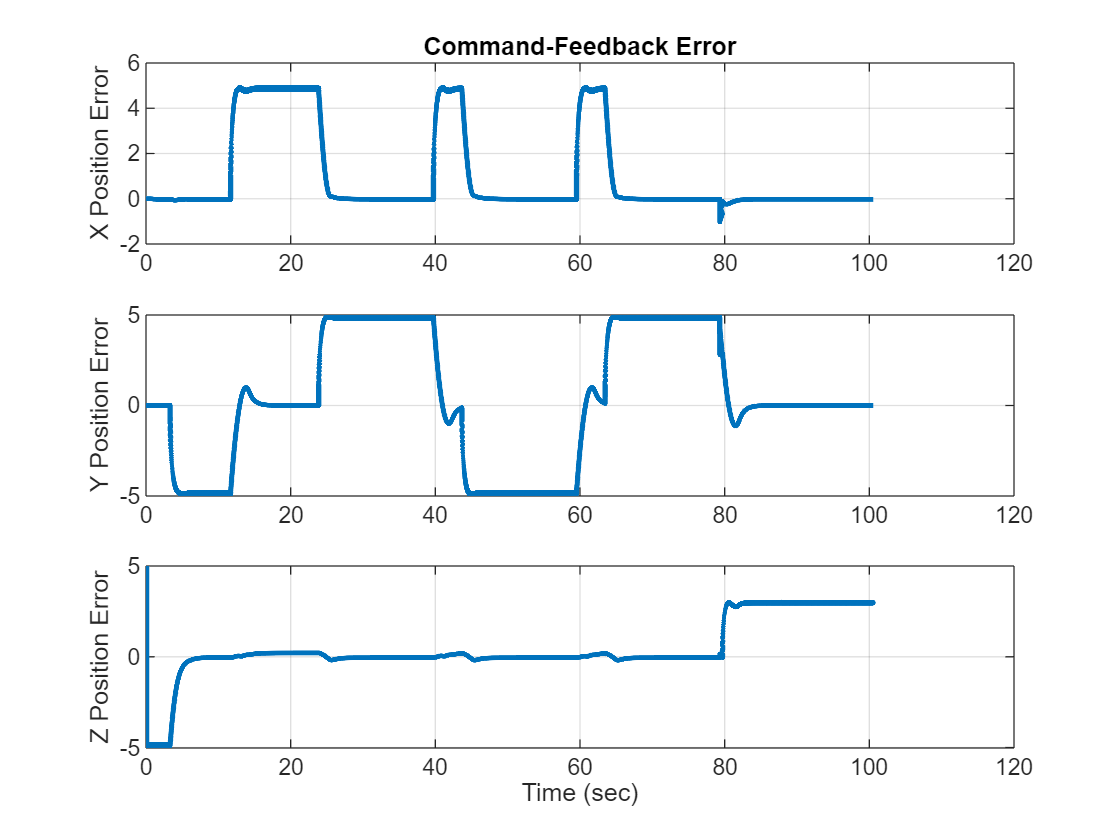

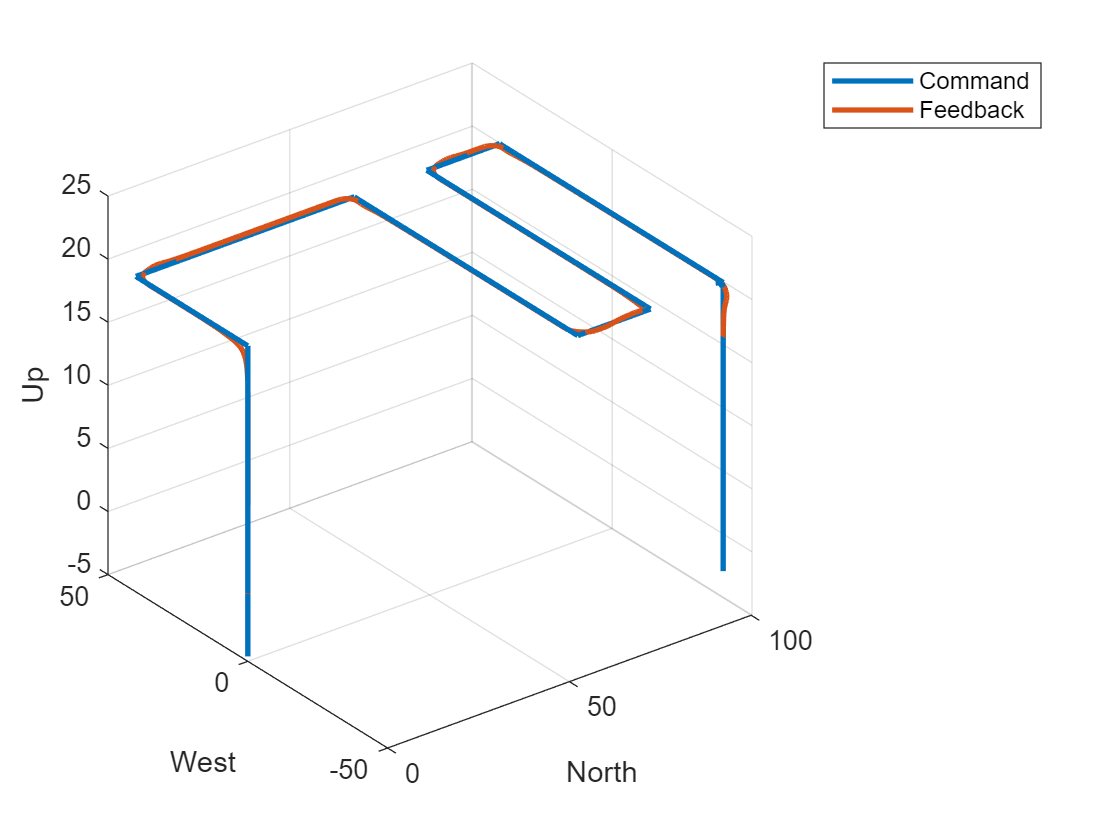

exampleHelperPlotHoverControlTrackingResults(simDataUntuned)

### Motor Control Tuning

The bandwidth of the outer loop of the cascade control are 20 Hz and 50 Hz for position and attitude control respectively. For the motor loop you see the bandwidth is 100 Hz and tune the PID values.

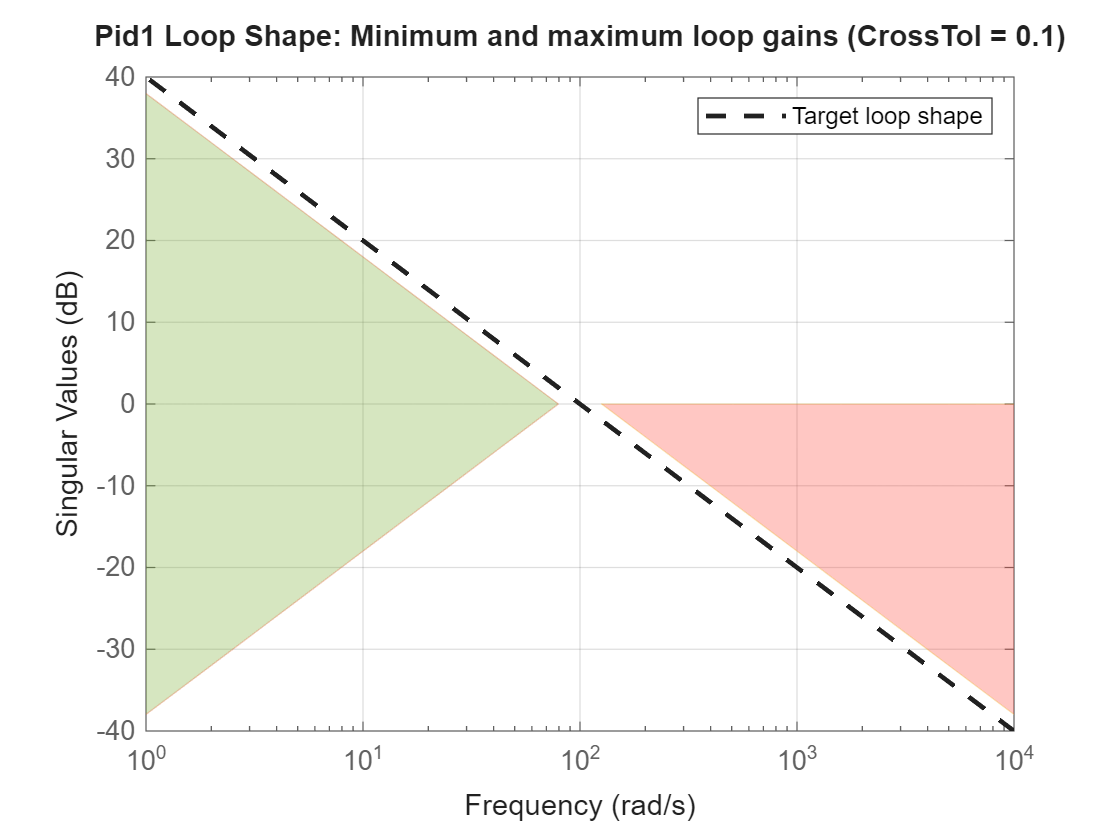

Final: Soft = 2.02, Hard = -Inf, Iterations = 42


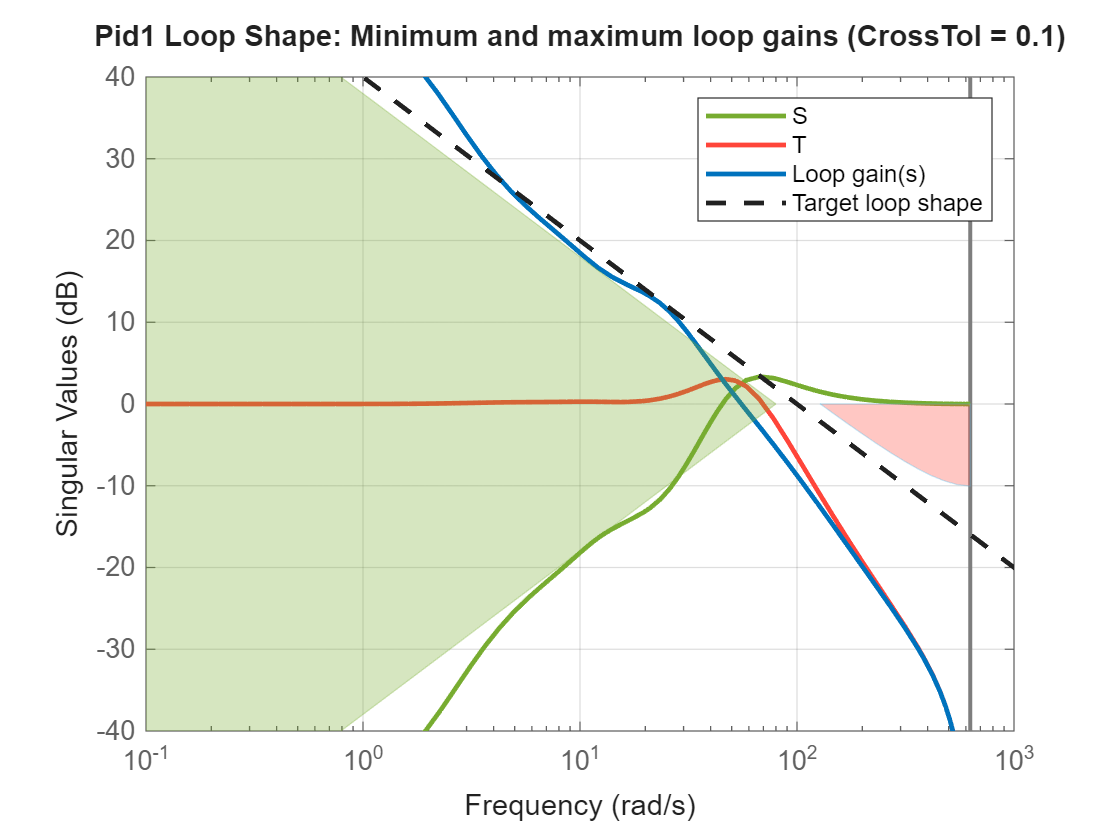

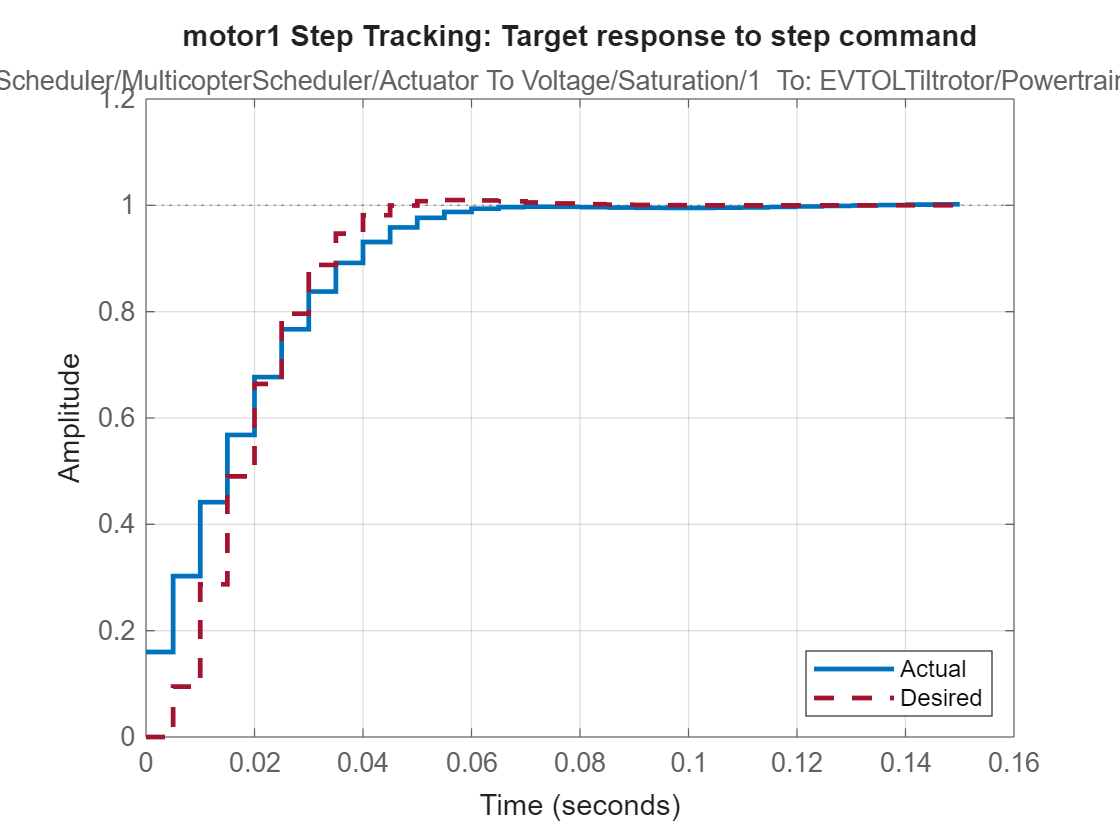

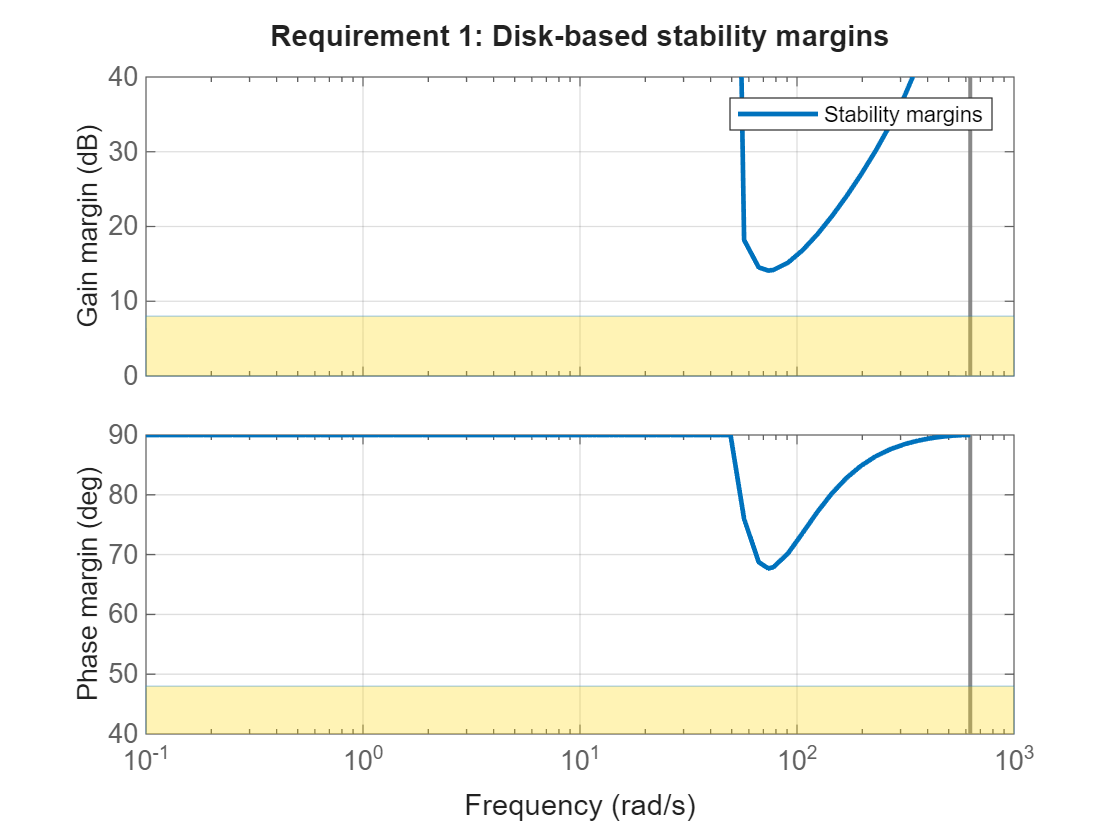

% Step tracking tuner, time constant
tuningTarget.tau = 0.01; % Time constant (s)
% Bandwidth of Motor controller multiple of higher level controller bandwidth
tuningTarget.wc = 100;  % Loopshaping cut off frequency (Hz)
% Gain margin and phase margin Gain margin of 20 dB and phase margin of 60 degrees
tuningTarget.gain = 8;
tuningTarget.phase = 48; 

% Tune control parameters for multiple objectives
motorSLtuner

The stability margin and step response of the system is within accepatable range. For each requirement, the requirement is satisfied if f < 1 and violated if f >1. fSoft is the vector of minimized f values. The largest of the minimized f values is displayed as Soft, it is greater than 1 but the loop shaping and step tracking are within accepatable range.

Run the simulation with tuned control parameters.

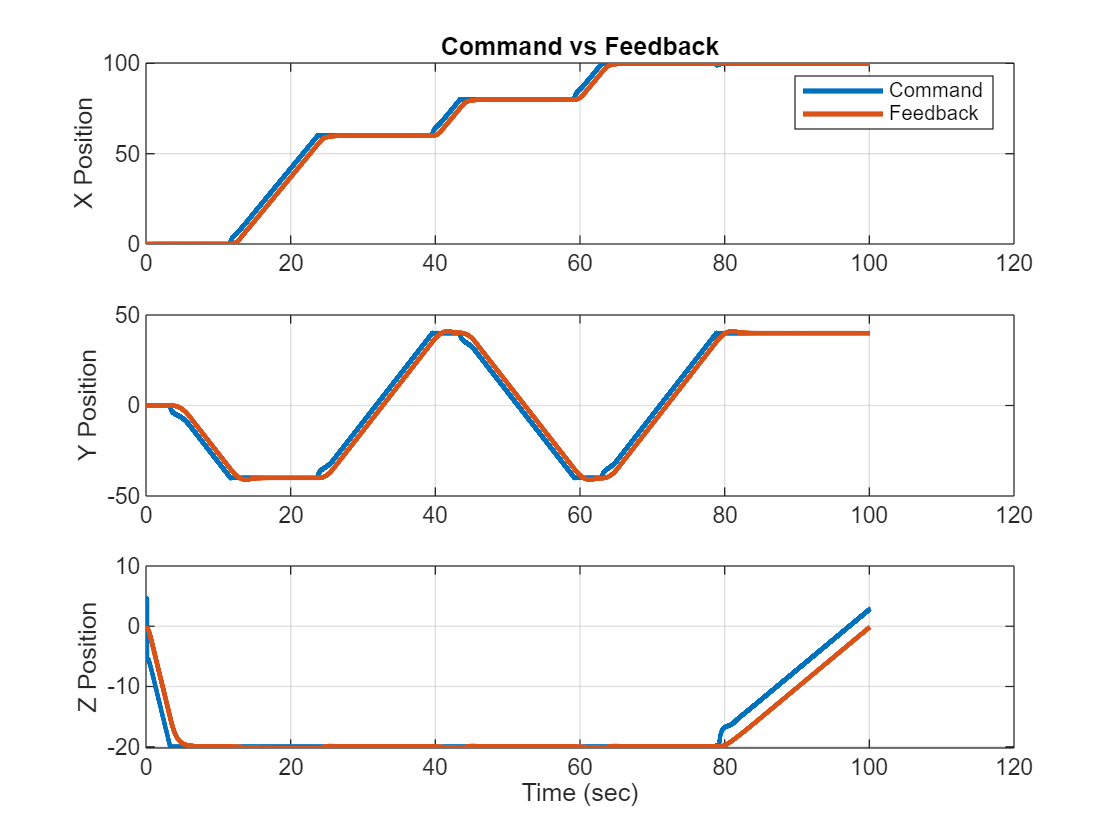

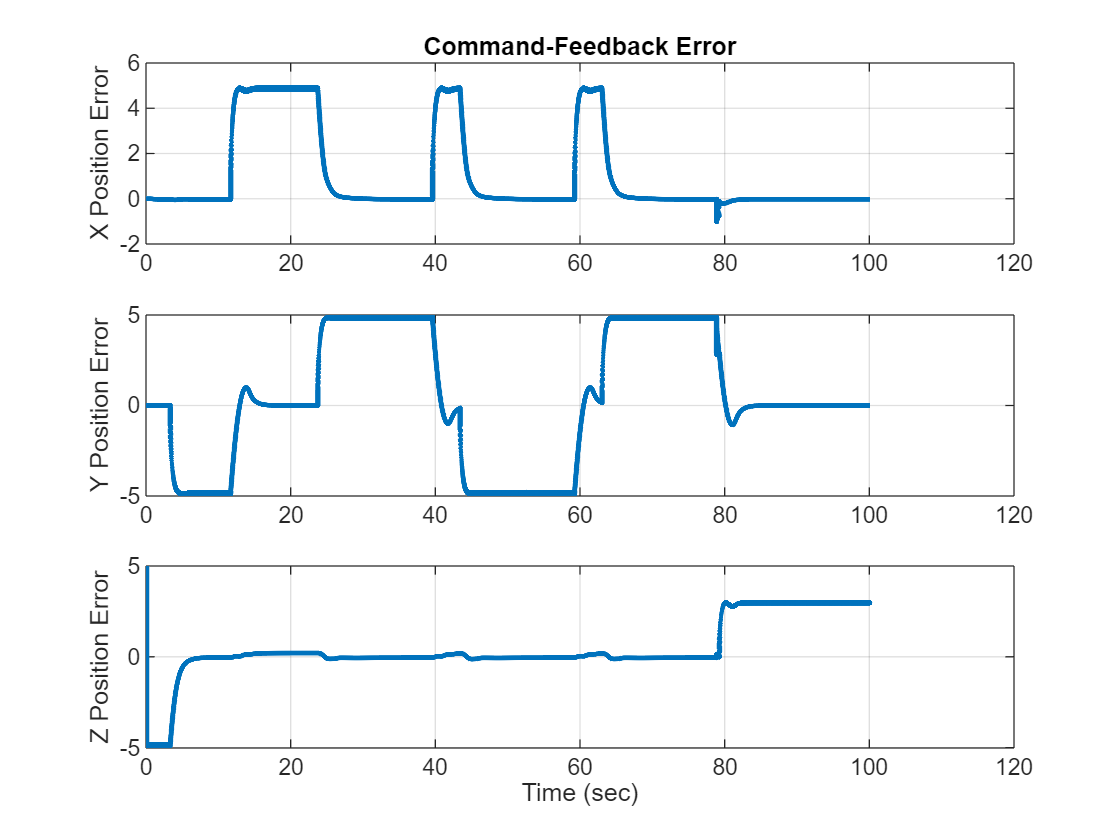

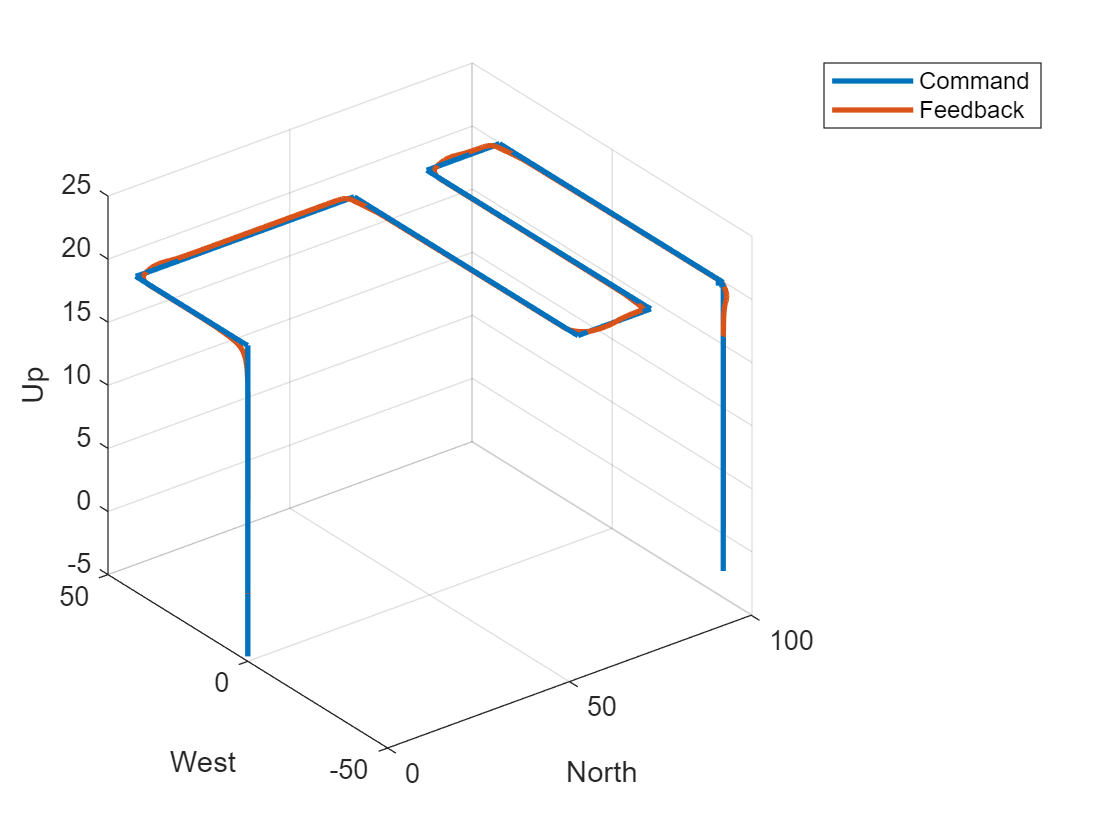

SetupHoverConfiguration;
SetupHoverGuidanceMission;
simDataTuned = sim(mdl);
exampleHelperPlotHoverControlTrackingResults(simDataTuned)

## Comparison

Comparison of response for tuned and untuned motor control.

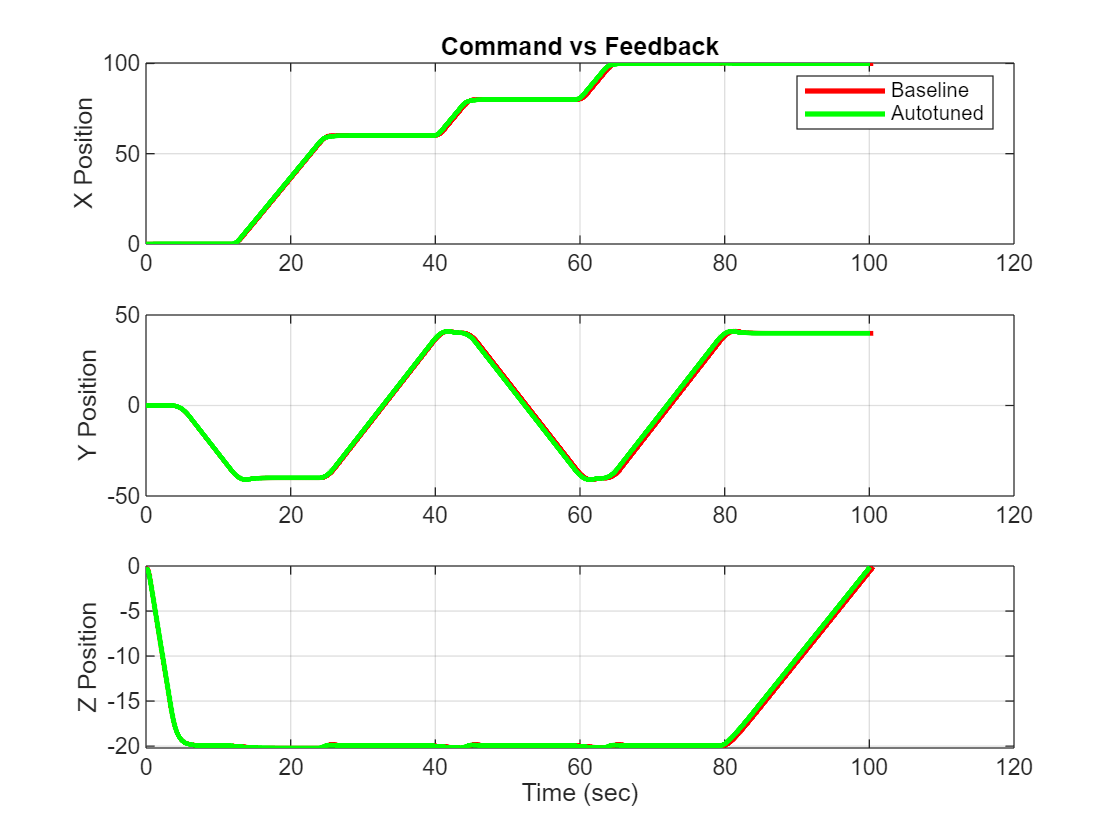

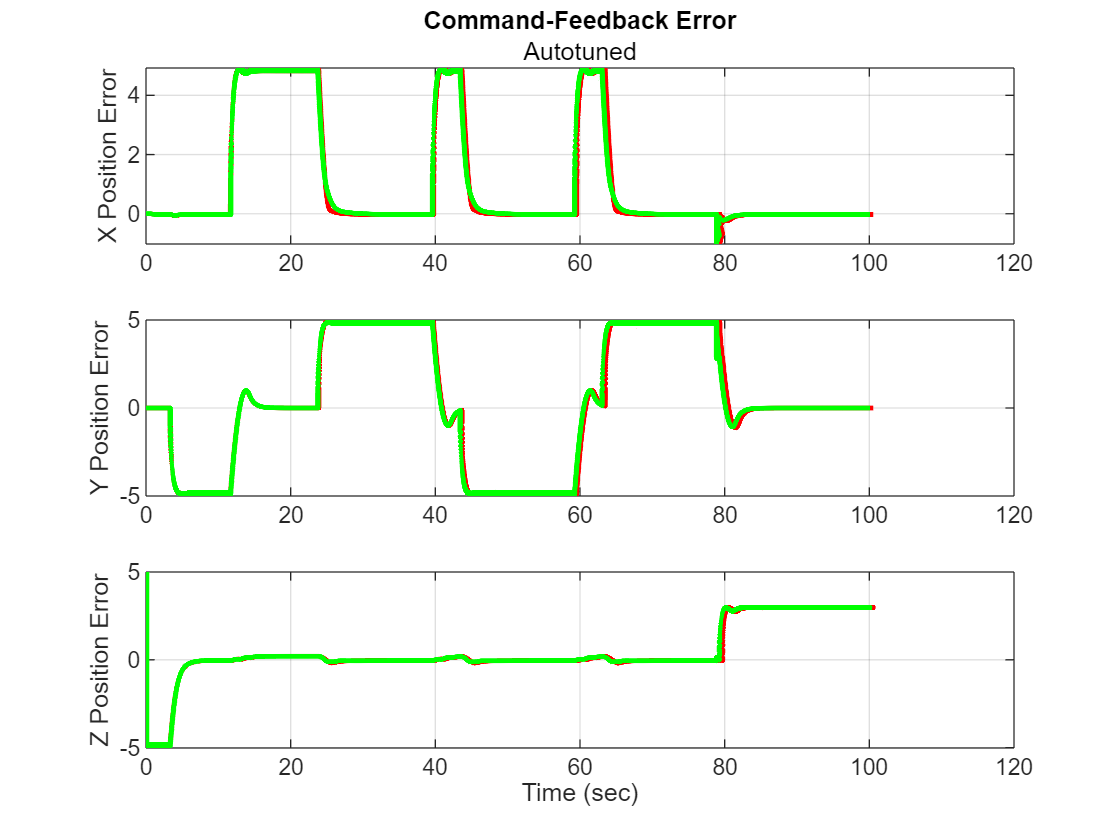

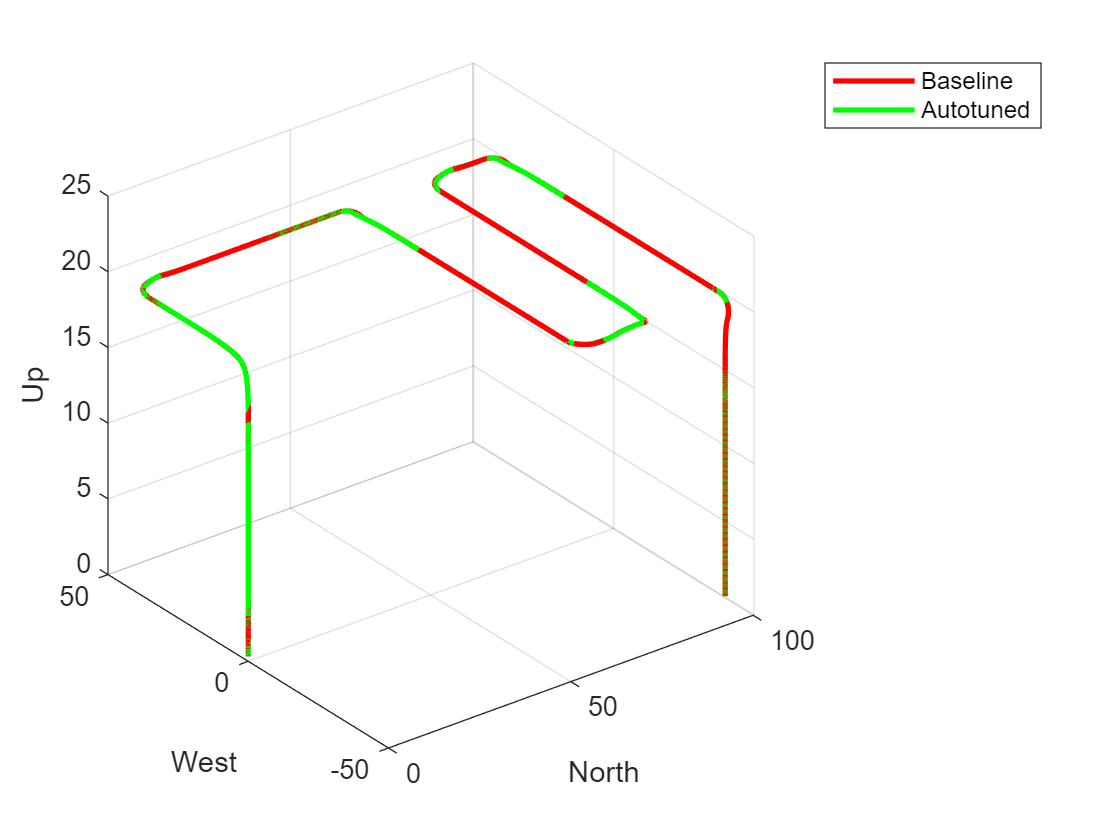

exampleHelperPlotHoverControlTrackingComparison(simDataUntuned,simDataTuned)

The system demonstrates robust stability and sufficient phase and gain margins, indicating resilience to model uncertainties and external disturbances.

## **References**

[1] N., Pavan. (2020). “Design of Tiltrotor VTOL and Development of Simulink Environment for Flight Simulations.” Master's Thesis, Indian Institute of Technology Madras, 2020 [here](https://www.researchgate.net/profile/Pavan-N/publication/351154528_Design_of_Tiltrotor_VTOL_and_Development_of_Simulink_Environment_for_Flight_Simulations/links/608ab0eba6fdccaebdf77bc8/Design-of-Tiltrotor-VTOL-and-Development-of-Simulink-Environment-for-Flight-Simulations.pdf).